# Homework 7 (Solutions)

Math 3607, Spring 2022

Tae Eun Kim

clear

Solutions to *by-hand *problems are found in a separate pdf file named [hw07soln-by-hand.pdf](https://tek288a1.github.io/sp22m3607/homework/hw07soln-by-hand.pdf).

## Problem 4 (Orthnormal columns and orthogonal polynomials; adapted from FNC 3.3.3.)

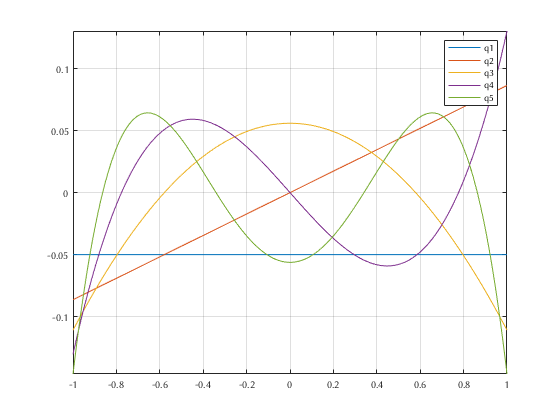

m = 400; n = 5;
x = linspace(-1, 1, m)';
V = x.^(0:n-1);
[Q,R] = qr(V,0);   % thin QR factorization

clf
plot(x, Q)
axis tight, grid on
legend('q1', 'q2', 'q3', 'q4', 'q5')

**Note 1.** The `plot` function smartly plots all columns of `Q` as functions of the common `x` when called with `plot(x, Q)`. This is the same as

Where does one learn about such tricks? Please read the very first paragraph of the help document for `plot`:

help plot

## Problem 5 (Gram-Schmidt in MATLAB; LM 12.6--2)

Below is a version which is more or less a direct translation of the Gram-Schmidt procedure:

We can have `A` overwirtten by `Q` to save memory storages. In addition, we can also get by without the auxilliary vector `v` introduced right after the if statement. The code included at the end of this document incorporates all these modifications. 

Let's check if the code works correctly.

m = 1000; n = 30;
A = rand(m,n);

**Using **`gs.m`**:**

[Q,R] = gs(A);
istriu(R)                    % Is R upper triangular?

ans = logical
   1

norm(Q'*Q - eye(n), 'inf')   % Is Q orthogonal?

ans =       2.67212467430777e-14

norm(Q*R - A, 'inf')         % Is Q*R = A?

ans =       6.93889390390723e-16

**Using **`qr:`

[Q0,R0] = qr(A,0);
istriu(R0)                   % Is R upper triangular?

ans = logical
   1

norm(Q0'*Q0 - eye(n), 'inf') % Is Q orthogonal?

ans =       1.92727778181023e-15

norm(Q0*R0 - A, 'inf')       % Is Q*R = A?

ans =       2.50188758599279e-13

**Note 1.**

Several runs with random matrices shows that both code works as expected. However, $Q$ and $R$ produced the codes are not necessarily the same. 

norm(Q-Q0, 'inf')

ans =           1.27133151013133

as more is going on for MATLAB's `qr `to ensure numerical stability. 

**Note 2.**

There is a visually convenient way to confirm the triangularity of $R$:

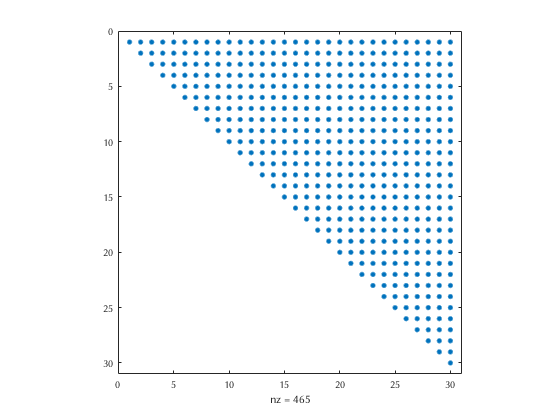

spy(R)

To learn about this function, see

help spy

 spy Visualize sparsity pattern.
    spy(S) plots the sparsity pattern of the matrix S.
 
    spy(S,'LineSpec') uses the color and marker from the line
    specification string 'LineSpec' (See PLOT for possibilities).
 
    spy(S,markersize) uses the specified marker size instead of
    a size which depends upon the figure size and the matrix order.
 
    spy(S,'LineSpec',markersize) sets both.
 
    spy(S,markersize,'LineSpec') also works.

    Documentation for spy



## Functions Used

### Gram-Schmidt (for Problem 5)

function [Q,R] = gs(A)
    n = size(A,2);
    Q = A;
    R = zeros(n);
    for j = 1:n
        if j > 1
            R(1:j-1,j) = Q(:,1:j-1)' * Q(:,j);
            Q(:,j) = Q(:,j) - Q(:,1:j-1)*R(1:j-1,j);
        end
        R(j,j) = norm(Q(:,j));
        Q(:,j) = Q(:,j)/R(j,j);
    end
end